clearvars;
addpath('ego');
addpath('kwave');

# Image source method and kwave for room acoustics simulation

In the following we will simulate the propagation from an acoustic source to a receiver in a 2 dimensional rectangle room using the image source method and the matlab toolbox kwave. We will use the kwave implementation as a reference to analyse wether the image source method is accurate and how the image order affects that accuracy.

### Parameter initializazion

frequency = 0.25e6; % Signal frequency in Hz
dimension = 2^7; % Computational grid x and y dimensions
spacing = 50e-3/dimension; % Spacing between each point of the grid
c = 343; % speed of sound
alpha = 0;
p_source = [0,0,0]; % Source coordinates
p_receiver = [-8,8,8]; % Receiver coordinates

## kwave method

Filtering input signal...
  maximum frequency supported by kgrid: 439.04kHz (2 PPW)
  filter cutoff frequency: 292.6933kHz (3 PPW)
  computation complete.
Running k-Wave simulation...
  start time: 03-Nov-2021 08:04:03
  reference sound speed: 343m/s
  dt: 341.6545ns, t_end: 252.4827us, time steps: 740
  input grid size: 128 by 128 by 128 grid points (50 by 50 by 50mm)
  maximum supported frequency: 439.04kHz
  precomputation completed in 0.25021s
  starting time loop...
  estimated simulation time 7min 4.2253s...


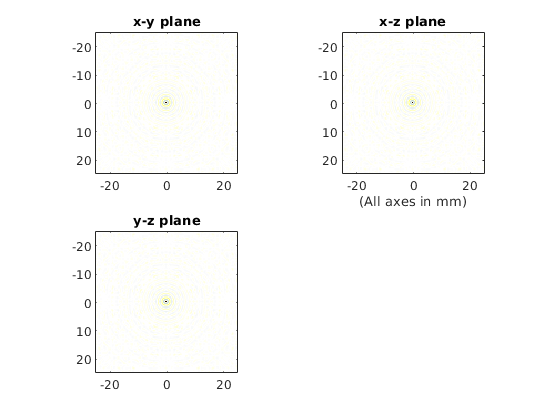

  simulation completed in 7min 0.16304s
  total computation time 7min 0.47111s


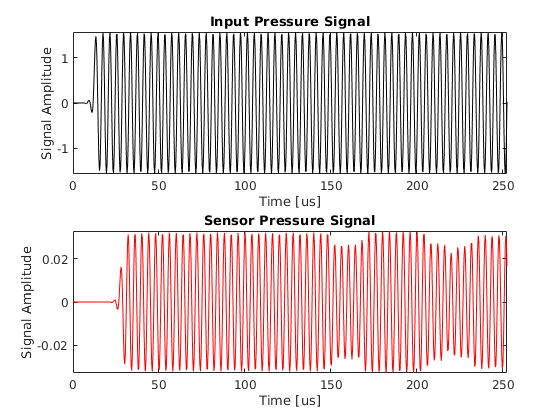

[t,scale] = point_source(p_source, p_receiver, frequency, dimension, spacing);

## Image source method

----------------------------------------
Plane and point coordinates for GeoGebra
----------------------------------------
Plane((0,0,0),(0,1,0),(0,0,1))
Plane((0,0,0),(0,0,1),(1,0,0))
Plane((128,0,0),(128,1,0),(128,0,1))
Plane((0,128,0),(1,128,0),(0,128,1))
Plane((0,0,0),(0,1,0),(1,0,0))
Plane((0,0,128),(1,0,128),(0,1,128))
(0,0,0)
(256,0,0)
(0,256,0)
(0,0,256)
(-256,0,0)
(256,256,0)
(256,0,256)
(0,-256,0)
(0,256,256)
(0,0,-256)
----------------------------------------


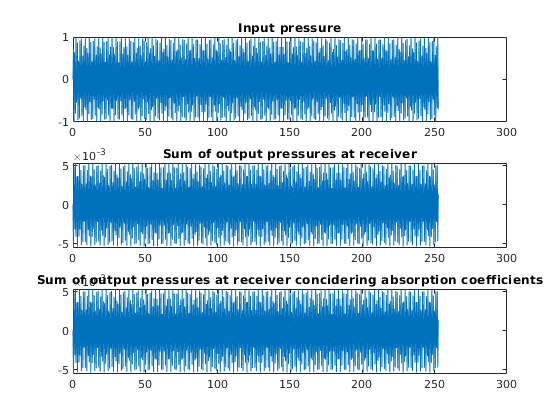

tot_output_pressure =          0   -0.0055    0.0049   -0.0007   -0.0031    0.0053   -0.0041    0.0003    0.0036   -0.0053    0.0037    0.0003   -0.0041    0.0053   -0.0032   -0.0009    0.0045   -0.0052    0.0027    0.0015   -0.0048    0.0050   -0.0021   -0.0021    0.0050   -0.0047    0.0015    0.0027   -0.0052    0.0044   -0.0009   -0.0032    0.0053   -0.0040    0.0002    0.0037   -0.0053    0.0036    0.0004   -0.0041    0.0053   -0.0031   -0.0010    0.0045   -0.0052    0.0026    0.0016   -0.0048    0.0050   -0.0020


image_order = 2;
alpha = [0 0 0 0 0 0];
[tot_output_pressure] = image_source_pressure_wave(p_source,p_receiver,dimension,dimension,dimension,(t*scale),c,frequency,image_order,alpha) 